clear all
clc



%%% https://markedsplass.fjordkraft.no/oppvarming/varmtvann/OSO-Charge-Smartstyringsenhet#product-details-tab-description
%%% kanskje bare skrive at vi bruker samme metode, og at det sparer 100kr i
%%% måneden

Varmeovn = 0.7; %kW  %%%% https://markedsplass.fjordkraft.no/oppvarming/varmeovner/aeno-led-premium-eco-smart-varmeovn-hvit#product-details-tab-specification

Varmepumpe_under7 = 2.3; %kW  %%%https://markedsplass.fjordkraft.no/oppvarming/varmepumpe/toshiba-seiya-nordic-25#product-details-tab-specification
Varmepumpe_fom7 = 3.2; %kW


%https://www.forbrukerradet.no/strompris/spotpriser/

f = readtable("spotpriser.csv","Delimiter", ";");

ff = f(:,"NO3");

temp = readtable("temp.csv","Delimiter", ";");

tempt_inv = temp.Lufttemperatur;
tempt = tempt_inv'; 


tempt(end) = [];
tempt_24 = reshape(tempt, [24, 366])'

tempt_24 =    -8.4000   -8.4000   -8.3000   -8.5000   -8.6000   -8.4000   -8.5000   -8.5000   -8.4000   -8.5000   -8.8000   -8.7000   -8.7000   -9.0000   -9.1000   -9.2000   -9.0000   -9.1000   -9.0000   -9.0000   -9.0000   -9.2000   -9.4000   -9.5000
   -9.6000   -9.8000   -9.7000  -10.1000  -10.2000  -10.5000  -10.7000  -10.9000  -11.1000  -11.3000  -11.3000  -10.9000  -10.8000  -11.3000  -12.1000  -13.0000  -13.3000  -13.1000  -12.9000  -12.8000  -12.8000  -13.1000  -13.4000  -13.4000
  -13.3000  -13.4000  -13.6000  -13.6000  -13.7000  -13.8000  -13.9000  -13.9000  -14.1000  -14.5000  -14.5000  -14.4000  -14.3000  -14.6000  -14.9000  -15.2000  -15.1000  -15.2000  -15.0000  -15.2000  -15.1000  -15.1000  -15.0000  -15.4000
  -15.4000  -15.7000  -15.9000  -16.1000  -16.8000  -16.5000  -16.4000  -16.3000  -16.8000  -16.9000  -16.7000  -16.8000  -17.2000  -17.7000  -17.8000  -19.2000  -19.2000  -19.9000  -20.7000  -21.4000  -21.7000  -22.4000  -23.0000  -23.3000
  -23.8000  -24.1000  -24


timer = [1:1:8784]; %%24*366
dager = [1:1:366]; 
T = f.NO1;
TT = T';
TTT = reshape(TT, [24, 366])';

Starttemp_varme_ute = 10;




Varmeovn_vektor = varmeovn(Starttemp_varme_ute,Varmeovn,tempt,TT);
pris_varmeovn = utsortere(Starttemp_varme_ute,tempt,Varmeovn_vektor);
pris_varmeovn_dager = reshape(pris_varmeovn, [24, 366])';


pris_varmepumpe_tot = varmepris(Varmepumpe_under7,Varmepumpe_fom7,tempt,TT)

pris_varmepumpe_tot =     1.7346    1.5795    0.8852    0.7895    0.7743    0.6846    0.7294    0.8075    0.8462    1.0387    1.5386    1.6934    1.8243    1.9291    2.0013    2.0162    2.0378    2.0958    2.0504    2.0349    2.0042    1.8791    1.6956    1.4199    1.2254    1.0823    1.0329    1.0413    1.1835    1.3454    1.5860    2.0007    2.1177    2.1542    2.2922    2.3715    2.5205    2.5434    2.5554    2.5786    2.6269    2.6096    2.4170    2.1532    2.0936    2.0778    2.0191    1.9078    1.8725    1.8851


pris_varmepumpe = utsortere(Starttemp_varme_ute,tempt,pris_varmepumpe_tot)

pris_varmepumpe =     1.7346    1.5795    0.8852    0.7895    0.7743    0.6846    0.7294    0.8075    0.8462    1.0387    1.5386    1.6934    1.8243    1.9291    2.0013    2.0162    2.0378    2.0958    2.0504    2.0349    2.0042    1.8791    1.6956    1.4199    1.2254    1.0823    1.0329    1.0413    1.1835    1.3454    1.5860    2.0007    2.1177    2.1542    2.2922    2.3715    2.5205    2.5434    2.5554    2.5786    2.6269    2.6096    2.4170    2.1532    2.0936    2.0778    2.0191    1.9078    1.8725    1.8851


pris_varmepumpe_dager = reshape(pris_varmepumpe, [24, 366])';

Faktisk_pris_varmepumpe = zeroColumnsInInterval(pris_varmepumpe_dager,9,14);

varmepumpeee = varmepumpen(TT,pris_varmepumpe_tot);
DEN_faktiske_varmepumpe = reshape(varmepumpeee, [24, 366])';

varmepumpe_tester_1 = lavprismatrise(Faktisk_pris_varmepumpe,TTT,7,8);
varmepumpe_tester_2 = lavprismatrise(varmepumpe_tester_1,TTT,17,18);
varmepumpe_tester_3 = lavprismatrise(varmepumpe_tester_2,TTT,19,20);
varmepumpe_tester_4 = lavprismatrise(varmepumpe_tester_3,TTT,21,22);
varmepumpe_tester = lavprismatrise(varmepumpe_tester_4,TTT,23,24);



Faktisk_pris_varmeovn = zeroColumnsInInterval(pris_varmeovn_dager,9,14);


varmeovn_tester_1 = lavprismatrise(Faktisk_pris_varmeovn,TTT,1,2);
varmeovn_tester_2 = lavprismatrise(varmeovn_tester_1,TTT,16,17);
varmeovn_tester_3 = lavprismatrise(varmeovn_tester_2,TTT,18,20);
varmeovn_tester_4 = lavprismatrise(varmeovn_tester_3,TTT,21,22);
varmeovn_tester = lavprismatrise(varmeovn_tester_4,TTT,23,24);

totalpris = varmeovn_tester + DEN_faktiske_varmepumpe; %pris_varmepumpe_dager
totalpris_forb = totalpris./TTT

totalpris_forb =     2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575
    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    1.8975    1.8975    1.8975    1.8400    1.8400    1.8400    2.4000    2.4000    2.4000    2.4000    2.4000    2.4575    2.4575    2.4575    2.4575    2.4575
    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    2.4575    2.4575    2.4000    2.4000    2.4000    2.4000    2.4000    2.4575    2.4575    2.4575
    2.4575    2.4575    2.4575    2.4575    2.4575    2.4575    2.4000    2.4000    1.8400    1.8400    1.8400    1.8400    1.8400    1.8400    2.4000    2.4000    2.4000    2.4000    2.3425    2.4000    2.4000    2.4000    2.4000    2.4000
    2.4000    2.400


A = Varmeovn * ones(366, 24);

Varmepumpe_uten_AI = reshape(pris_varmepumpe_tot, [24, 366])'

Varmepumpe_uten_AI =     1.7346    1.5795    0.8852    0.7895    0.7743    0.6846    0.7294    0.8075    0.8462    1.0387    1.5386    1.6934    1.8243    1.9291    2.0013    2.0162    2.0378    2.0958    2.0504    2.0349    2.0042    1.8791    1.6956    1.4199
    1.2254    1.0823    1.0329    1.0413    1.1835    1.3454    1.5860    2.0007    2.1177    2.1542    2.2922    2.3715    2.5205    2.5434    2.5554    2.5786    2.6269    2.6096    2.4170    2.1532    2.0936    2.0778    2.0191    1.9078
    1.8725    1.8851    1.8858    1.8028    1.7605    1.8858    2.0243    2.0924    2.1179    2.1289    2.1444    2.1286    2.1179    2.1124    2.1231    2.2400    2.3759    2.6565    2.6787    2.5515    2.3643    2.2342    2.1121    2.0595
    2.0848    2.0555    2.0386    2.0320    2.0213    2.0991    2.3654    2.7682    2.9782    3.0671    2.9948    2.9434    2.8226    2.7988    2.9991    3.2110    3.4425    4.3379    4.7097    4.0699    3.3728    3.2563    3.0886    2.8922
    2.8787    2

Varmeovn_uten_AI = Faktisk_pris_varmeovn./TTT %varmeovn_ny(tempt_24,A)

Varmeovn_uten_AI =     0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600         0         0         0         0         0         0    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600
    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600         0         0         0         0         0         0    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600
    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600         0         0         0         0         0         0    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600
    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600         0         0         0         0         0         0    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600
    0.5600    0.5

uten_AI_r = Varmeovn_uten_AI + Varmepumpe_uten_AI

uten_AI_r =     2.2946    2.1395    1.4452    1.3495    1.3343    1.2446    1.2894    1.3675    0.8462    1.0387    1.5386    1.6934    1.8243    1.9291    2.5613    2.5762    2.5978    2.6558    2.6104    2.5949    2.5642    2.4391    2.2556    1.9799
    1.7854    1.6423    1.5929    1.6013    1.7435    1.9054    2.1460    2.5607    2.1177    2.1542    2.2922    2.3715    2.5205    2.5434    3.1154    3.1386    3.1869    3.1696    2.9770    2.7132    2.6536    2.6378    2.5791    2.4678
    2.4325    2.4451    2.4458    2.3628    2.3205    2.4458    2.5843    2.6524    2.1179    2.1289    2.1444    2.1286    2.1179    2.1124    2.6831    2.8000    2.9359    3.2165    3.2387    3.1115    2.9243    2.7942    2.6721    2.6195
    2.6448    2.6155    2.5986    2.5920    2.5813    2.6591    2.9254    3.3282    2.9782    3.0671    2.9948    2.9434    2.8226    2.7988    3.5591    3.7710    4.0025    4.8979    5.2697    4.6299    3.9328    3.8163    3.6486    3.4522
    3.4387    3.2527    

%uten_AI = reshape(uten_AI_r, [24, 366])';
uten_AI_forb = uten_AI_r./TTT

uten_AI_forb = 1.0e+03 *

    0.0030    0.0031    0.0038    0.0039    0.0040    0.0042    0.0041    0.0039    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0030    0.0031    0.0032
    0.0034    0.0035    0.0035    0.0035    0.0034    0.0033    0.0031    0.0029    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0028    0.0028    0.0028    0.0028    0.0028    0.0029    0.0029    0.0029    0.0029    0.0030
    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0029    0.0029    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0029    0.0029    0.0028    0.0028    0.0028    0.0028    0.0028    0.0029    0.0029    0.0029
    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0028    0.0028    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0027    0.0027    0.0027    0.0026    0.0026    0.0026    0.0027    0.0027    0.0027    0.0027
    0.0027


eff_varmepumpe_alene_uten_AI = Varmepumpe_uten_AI./TTT

eff_varmepumpe_alene_uten_AI =     2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000
    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000
    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000
    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000    2.3000
    2

eff_varmepumpe_alene_med_AI = DEN_faktiske_varmepumpe./TTT

eff_varmepumpe_alene_med_AI =     1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975
    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8400    1.8400    1.8400    1.8400    1.8400    1.8400    1.8400    1.8400    1.8975    1.8975    1.8975    1.8975    1.8975
    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8400    1.8400    1.8400    1.8400    1.8400    1.8975    1.8975    1.8975
    1.8975    1.8975    1.8975    1.8975    1.8975    1.8975    1.8400    1.8400    1.8400    1.8400    1.8400    1.8400    1.8400    1.8400    1.8400    1.8400    1.8400    1.8400    1.7825    1.8400    1.8400    1.8400    1.8400    1.8400
    1.

eff_varmeovn_alene_uten_AI = pris_varmeovn_dager./TTT

eff_varmeovn_alene_uten_AI =     0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600
    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600
    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600
    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600
    0.5

eff_varmeovn_alene_med_AI = varmeovn_tester./TTT

eff_varmeovn_alene_med_AI =     0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600         0         0         0         0         0         0    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600
    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600         0         0         0         0         0         0    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600
    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600         0         0         0         0         0         0    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600
    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600         0         0         0         0         0         0    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600
    0.56

%%% kanskje legge inn flere på samme for at det skal se mer realistisk ut.


Varmeovn_dag_for_dag = sum(Faktisk_pris_varmeovn');
Varmeovn_dag_for_dag_sumsum = sum(Varmeovn_dag_for_dag); 


Varmepumpe_dag_for_dag = sum(Faktisk_pris_varmepumpe');
Varmepumpe_dag_for_dag_sumsum = sum(Varmepumpe_dag_for_dag);

tester_dag_for_dag = sum(totalpris');
tester_dag_for_dag_uten_AI = sum(uten_AI_r')

tester_dag_for_dag_uten_AI =    46.1702   57.6161   61.4351   80.5299  160.8960   83.2094   79.3856   90.8536   91.1698   91.6646   91.9126   89.3173   66.0644   69.6831   77.9346  118.3342   85.6674   82.0919   74.5728   68.6109   54.4200   52.6385   50.2594   44.5719   69.1719   55.0925   55.0534   52.5711   64.9684   59.5962   51.6319   50.5503   52.0979   43.4312       NaN   45.8848   58.1139   73.8091   79.3669   64.4337   62.3314   58.8380   66.8764   64.6279   62.4842   63.0503   53.4234   57.7028   51.3935   59.0397




totalpris_med_AI = sum(tester_dag_for_dag)

totalpris_med_AI = 1.2776e+04

totalpris_uten_AI = sum(tester_dag_for_dag_uten_AI,'omitnan')

totalpris_uten_AI = 1.5725e+04



BESPARELSE = totalpris_uten_AI - totalpris_med_AI

BESPARELSE = 2.9491e+03

%plot(timer,TT);

dag= [1:1:24];




%%% Finne ut når man bør bruke støm

% figure()
% bar(dag,TTT(1,:),'w')
% 
% hold on
% 
% plot(dag,varmepumpe_tester(1,:),'b')
% 
% legend( 'strømpris','kostnadd')
% hold off

valgt_dag = 5

valgt_dag = 5

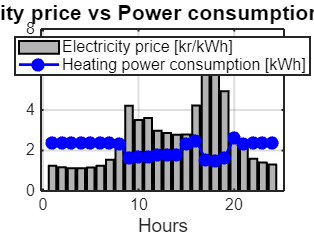



figure()

% Bar chart for strømpris
bar(dag, TTT(valgt_dag,:), 'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'k', 'LineWidth', 1.5); % Grå farge med svart kant
hold on

% Line plot for varmepumpe kostnad
plot(dag,totalpris_forb(valgt_dag,:), 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b', 'MarkerSize', 8); % Blå linje med fylte markører

% Legg til grid for bedre lesbarhet
grid on

% Tilpass akser og skriftstørrelse
set(gca, 'FontSize', 12, 'LineWidth', 1.5); % Større skrift og tykkere akselinjer
xlabel('Hours', 'FontSize', 14);
%ylabel('kWh', 'FontSize', 14);
title('Electricity price vs Power consumption, with AI', 'FontSize', 16);

% Legg til legend med bedre plassering
legend('Electricity price [kr/kWh]', 'Heating power consumption [kWh]', 'Location', 'best', 'FontSize', 12);

hold off

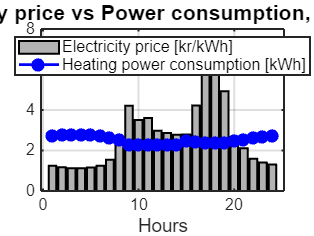


figure()

% Bar chart for strømpris
bar(dag, TTT(valgt_dag,:), 'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'k', 'LineWidth', 1.5); % Grå farge med svart kant
hold on

% Line plot for varmepumpe kostnad
plot(dag,uten_AI_forb(valgt_dag,:), 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b', 'MarkerSize', 8); % Blå linje med fylte markører

% Legg til grid for bedre lesbarhet
grid on

% Tilpass akser og skriftstørrelse
set(gca, 'FontSize', 12, 'LineWidth', 1.5); % Større skrift og tykkere akselinjer
xlabel('Hours', 'FontSize', 14);
%ylabel('kWh', 'FontSize', 14);
title('Electricity price vs Power consumption, without AI', 'FontSize', 16);

% Legg til legend med bedre plassering
legend('Electricity price [kr/kWh]', 'Heating power consumption [kWh]', 'Location', 'best', 'FontSize', 12);

hold off

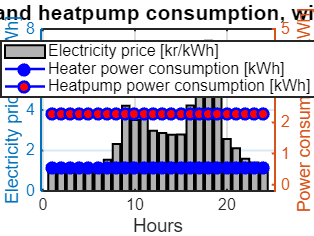


figure()

% Bar chart for strømpris
yyaxis left;
bar(dag, TTT(valgt_dag,:), 'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'k', 'LineWidth', 1.5); % Grå farge med svart kant
ylabel('Electricity price [kr/kWh]');
%ylim([-0.2, 10])
hold on

% Line plot for varmepumpe kostnad
yyaxis right;
plot(dag,eff_varmeovn_alene_uten_AI(valgt_dag,:), 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b', 'MarkerSize', 8); % Blå linje med fylte markører
plot(dag,eff_varmepumpe_alene_uten_AI(valgt_dag,:), 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'r', 'MarkerSize', 8); % Blå linje med fylte markører

ylabel('Power consumption [kWh]');
ylim([-0.2, 5]);

% Legg til grid for bedre lesbarhet
grid on

% Tilpass akser og skriftstørrelse
set(gca, 'FontSize', 12, 'LineWidth', 1.5); % Større skrift og tykkere akselinjer
xlabel('Hours', 'FontSize', 14);
%ylabel('kWh', 'FontSize', 14);
title('Heater and heatpump consumption, without AI', 'FontSize', 16);

% Legg til legend med bedre plassering
legend('Electricity price [kr/kWh]', 'Heater power consumption [kWh]', 'Heatpump power consumption [kWh]', 'Location', 'best', 'FontSize', 12);

hold off

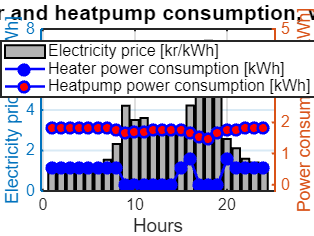



figure()

% Bar chart for strømpris
yyaxis left;
bar(dag, TTT(valgt_dag,:), 'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'k', 'LineWidth', 1.5); % Grå farge med svart kant
ylabel('Electricity price [kr/kWh]');
%ylim([-0.2, 10])

%
hold on

yyaxis right;
plot(dag,eff_varmeovn_alene_med_AI(valgt_dag,:), 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b', 'MarkerSize', 8); % Blå linje med fylte markører
plot(dag,eff_varmepumpe_alene_med_AI(valgt_dag,:), 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'r', 'MarkerSize', 8); % Blå linje med fylte markører

ylabel('Power consumption [kWh]');
ylim([-0.2, 5]);

% Line plot for varmepumpe kostnad



% Legg til grid for bedre lesbarhet
grid on

% Tilpass akser og skriftstørrelse
set(gca, 'FontSize', 12, 'LineWidth', 1.5); % Større skrift og tykkere akselinjer
xlabel('Hours', 'FontSize', 14);
%ylabel('kWh', 'FontSize', 14);
title('Heater and heatpump consumption, with AI', 'FontSize', 16);

% Legg til legend med bedre plassering
legend('Electricity price [kr/kWh]', 'Heater power consumption [kWh]', 'Heatpump power consumption [kWh]', 'Location', 'best', 'FontSize', 12);

hold off